## MIMO雷达目标定位DOA的CRB计算，计算精度存在问题

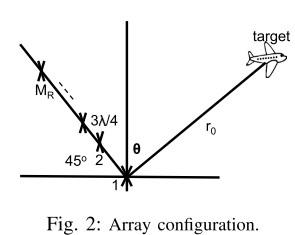

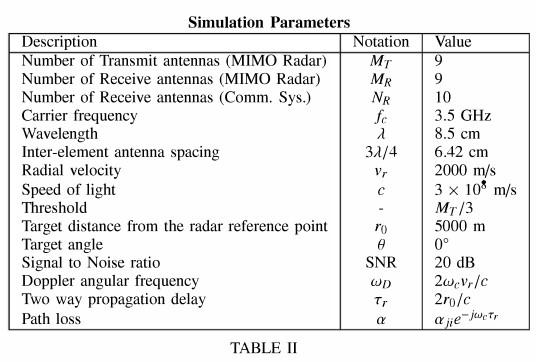

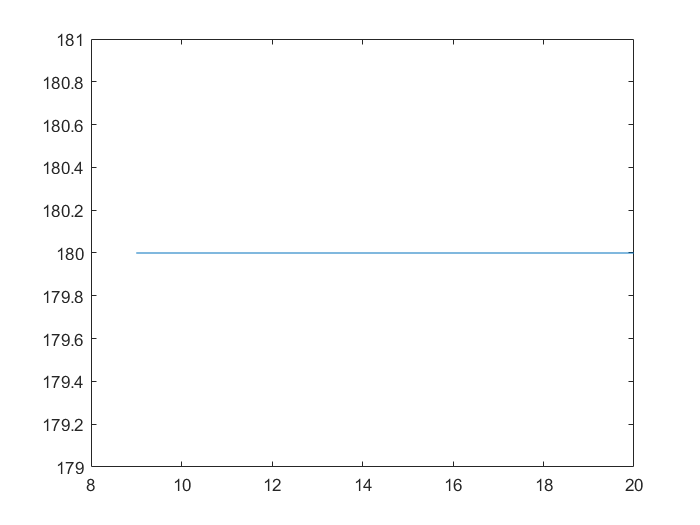

clear,clc,close,clf
CRB = zeros(20-8,1);
CRB_angle = zeros(20-8,1);
for nj = 9:20
% nj = 9;
M_T = 9;
M_R = nj;
Rx = eye(M_T);
fc = 3.5e9;
wc = 2*pi*fc;
c = physconst('LightSpeed');
lamda = c/fc;
ant_spacing = 3*lamda/4;
r0 = 5e3;
SNR = 100;
theta = 0;
ant_theta = 135;
elementPos_t = [(0:ant_spacing:ant_spacing*(M_T-1)).*cosd(ant_theta);(0:ant_spacing:ant_spacing*(M_T-1)).*sind(ant_theta)];
elementPos_r = [(0:ant_spacing:ant_spacing*(M_R-1)).*cosd(ant_theta);(0:ant_spacing:ant_spacing*(M_R-1)).*sind(ant_theta)];
tau_t = zeros(M_T,1);
tau_r = zeros(M_R,1);
at = zeros(M_T,1);
ar = zeros(M_R,1);
at_D = zeros(M_T,1);
ar_D = zeros(M_R,1);
% 生成steering vector
% ang = [45;0];
% elementPos = 0:-1*ant_spacing:-1*ant_spacing*(M_T-1);
% sv = steervec(elementPos/lamda,ang);
for ni = 1:M_T
    tau_t(ni,1) = [sind(theta);cosd(theta)].'*elementPos_t(:,ni)/c;
    at(ni,1) = exp(-1i*wc*tau_t(ni,1));
    at_D(ni,1) = (-1i*wc/c*(elementPos_t(1,ni)*cosd(theta)-elementPos_t(2,ni)*sind(theta)))*at(ni,1);
end
for ni = 1:M_R
    tau_r(ni,1) = [sind(theta);cosd(theta)].'*elementPos_r(:,ni)/c;
    ar(ni,1) = exp(-1i*wc*tau_r(ni,1));
    ar_D(ni,1) = (-1i*wc/c*(elementPos_r(1,ni)*cosd(theta)-elementPos_r(2,ni)*sind(theta)))*ar(ni,1);
end
CRB(nj-8) = (1/(2*SNR))/(M_R*at_D'*Rx.'*at_D-at'*Rx.'*at*norm(ar_D)^2-(M_R*abs(at'*Rx.'*at_D)^2)/(at'*Rx.'*at));
CRB_angle(nj-8) = rad2deg(angle(CRB(nj-8)));
end
plot(9:20,CRB_angle);

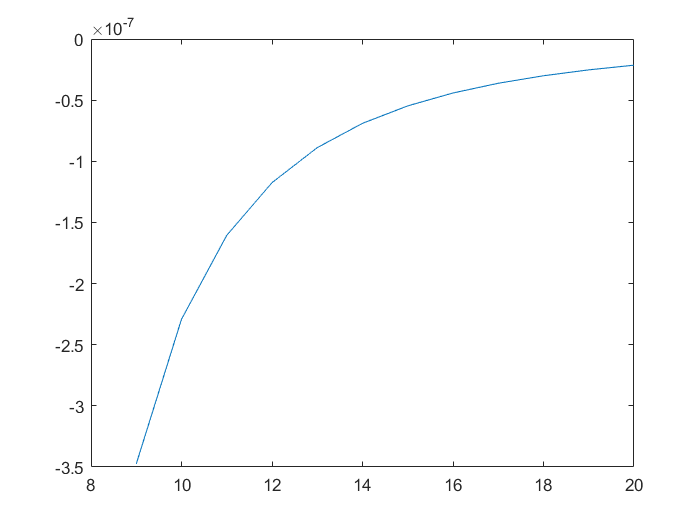

plot(9:20,CRB);

% -(wc*exp(-(wc*(y*cos(theta) + x*sin(theta))*1i)/c)*sin(theta)*1i)/c
% for ni = 1:M_T
%     tau_t(ni,1) = [sind(theta);cosd(theta)].'*elementPos_t(:,ni)/c;
%     at(ni,1) = exp(-1i*wc*tau_t(ni,1)); 
%     at_D(ni,1) = -(wc*exp(-(wc*elementPos_t(ni)*sind(theta)*1i)/c)*sind(theta)*1i)/c;
% end
% for ni = 1:M_R
%     tau_r(ni,1) = sind(theta)*elementPos_r(ni)/c;
%     ar(ni,1) = exp(-1i*wc*tau_r(ni,1));
%     ar_D(ni,1) = -(wc*exp(-(wc*elementPos_r(ni)*sind(theta)*1i)/c)*sind(theta)*1i)/c;
% end
% CRB(nj-8) = (1/(2*SNR))/(M_R*at_D'*Rx.'*at_D-at'*Rx.'*at*norm(ar_D)^2-(M_R*abs(at'*Rx.'*at_D)^2)/(at'*Rx.'*at));
% CRB_angle(nj-8) = abs(rad2deg(angle(CRB(nj-8))))-180;
% % CRB_angle(nj-8) = abs(imag(CRB(nj-8)))/abs(real(CRB(nj-8)));
% end
% plot(9:20,CRB_angle);